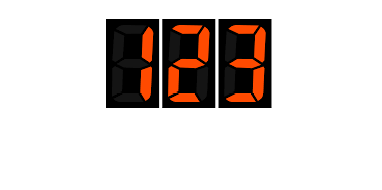

% Load image
[A,c] = imread('numbers.png');
A = A(1:90, 1:168);
imshow(A,c)

figure
[n,m] = size(A);
NM = n*m;

% Define labels
L = [1, 2, 3]; % 1 - white, 2 - black, 3 - red
% Define seeds
S = [8, 5, 2; 16, 8, 2; 23, 22, 2; 40, 5, 2; 55, 12, 2; 71, 4, 2; 86, 5, 2; 86, 20, 2; 65, 25, 2; 45, 26, 2; 20, 27, 2; 45, 35, 2; 85, 52, 2; 19, 51, 2; 17, 60, 2; 5, 68, 2; 28, 69, 2; 43, 69, 2; 60, 61, 2; 85, 64, 2; 87, 81, 2; 87, 91, 2; 61, 98, 2; 17, 107, 2; 3, 100, 2; 14, 118, 2; 39, 116, 2; 54, 121, 2; 81, 118, 2; 88, 135, 2; 62, 140, 2; 27, 143, 2; 2, 150, 2; 9, 164, 2; 41, 161, 2; 86, 162, 2; 
87, 168, 1; 50, 167, 1; 14, 168, 1; 7, 111, 1; 37, 112, 1; 70, 112, 1; 90, 109, 1; 90, 140, 1; 90, 68, 1;87, 55, 1; 61, 56, 1; 37, 56, 1; 7, 55, 1; 90, 8, 1;
78, 41, 3; 64, 39, 3; 55, 44, 3; 41, 44, 3; 27, 40, 3; 13, 45, 3; 45, 74, 3; 55, 67, 3; 66, 71, 3; 73, 67, 3; 79,79, 3; 48, 88, 3; 33, 96, 3; 22, 100, 3; 12, 100, 3; 10, 78, 3; 10, 133, 3; 11, 145, 3; 16, 157, 3; 38, 158, 3; 46, 151, 3; 45, 143, 3; 46, 132, 3; 57, 156, 3; 66, 152, 3; 76, 155, 3; 80, 144, 3; 79, 137, 3; 80, 129, 3];
T = 5000; % Number of steps
LD = zeros(NM, numel(L));  % initalize limiting distribution
img = zeros(n,m,3);
for p = 1:3
    for i = 1:n
        for j = 1:m
            img(i,j,p) = c(A(i,j)+1,p);
        end
    end
end

tic
W = sparse(calculate_weights(img,150));
toc

Elapsed time is 1.379627 seconds.


tic
H = construct_hamiltonian(W, 0.001);
toc

Elapsed time is 1.808025 seconds.


tic
parpool

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

parfor i = 1:numel(L) % use parfor if available
    sprintf("Working with label: %d", i)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(numel(A),1);
    for p = 1:subset_length
        if subset(p,2) + m*(subset(p,1)-1) > numel(A)
            p
            subset(p,2) + m*(subset(p,1)-1)
        end
        A_sub( subset(p,2) + m*(subset(p,1)-1) ) = 1;
    end
    state = 1/sqrt(subset_length) * sparse(A_sub);
    sprintf("The norm of our intial state vector is: %d", dot(full(state), full(state)))
    D = zeros(NM,T);
    for t = 1:T
        state = update_state(-1i, H, state);
        D(:,t) = retrieve_position(state);
    end
    sprintf("After %d steps, the norm is: %d", T, dot(full(state), full(state)))
    LD(:,i) = 1/T * sum(D,2);
    sprintf("Limiting distribution of label %d found", i)
end


ans = 

    "Working with label: 1"


ans = 

    "The norm of our intial state vector is: 1.000000e+00"


ans = 

    "After 5000 steps, the norm is: 1.000000e+00"


ans = 


ans = 

    "Working with label: 2"


ans = 

    "The norm of our intial state vector is: 1"


ans = 

    "Limiting distribution of label 1 found"

    "After 5000 steps, the norm is: 1.000000e+00"


ans = 

    "Limiting distribution of label 2 found"


ans = 

    "Working with label: 3"


ans = 

    "The norm of our intial state vector is: 1"


ans = 

    "After 5000 steps, the norm is: 1.000000e+00"


ans = 

    "Limiting distribution of label 3 found"



toc

Elapsed time is 528.516040 seconds.


delete(gcp('nocreate'))

Parallel pool using the 'Processes' profile is shutting down.


B_ld = zeros(n,m);
b = [4,3,2];
figure
for i = 1:n
    for j = 1:m
        k = find_seed(LD,i,j,m);
        B_ld(i,j) = k;
    end
end

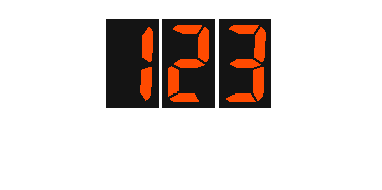

figure
imshow(B_ld,c(b,:))